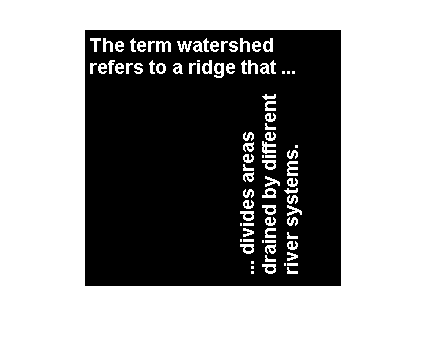

img = imread('text.png');
imshow(img);

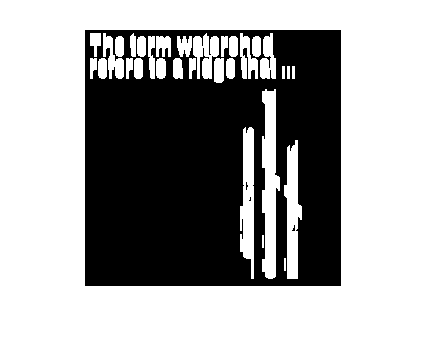

SE = strel('line', 11, 90); 
img2 = imdilate (img, SE);
imshow(img2);

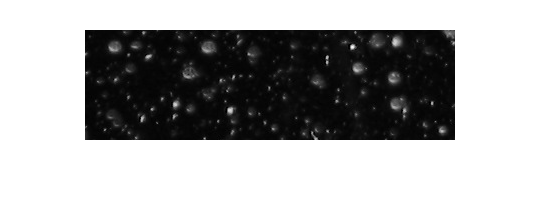


img3 = imread('snowflakes.png');
imshow(img3)

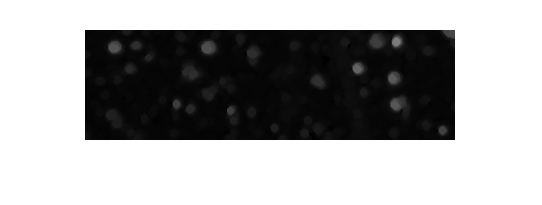

SE2 = strel('disk', 4);
imgOpen = imopen(img3, SE2);
imshow(imgOpen);

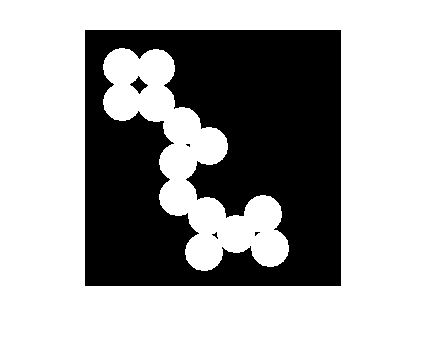


img4 = imread('circles.png'); 
imshow(img4)

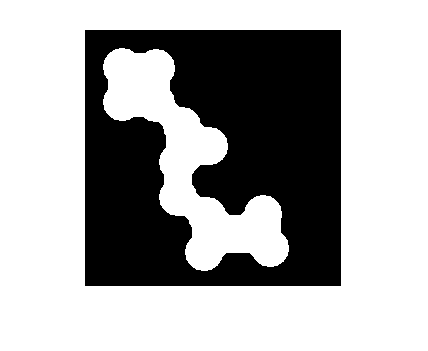

SE3 = strel('disk', 10);
imClose = imclose(img4, SE3);
imshow(imClose)

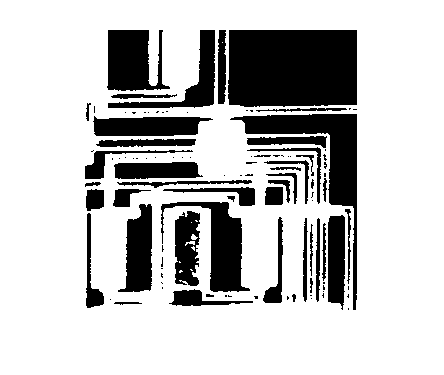


img5 = imread('circbw.tif');
imshow(img5)

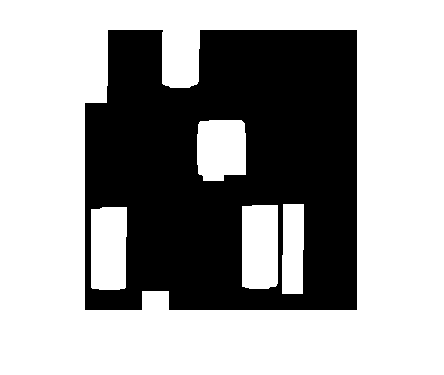

SE4 = strel('rectangle', [30 20]);
imgMorph = imopen(img5, SE4);
imshow(imgMorph)

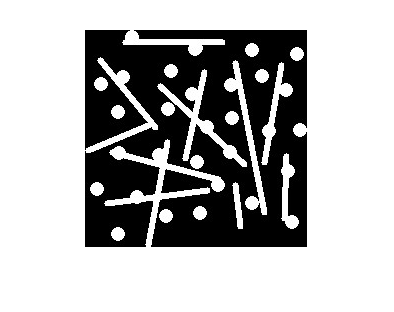

img6 = imread('sticks_circles.jpg');
imshow(img6)

SE6 = strel('disk', 6)

SE6 = strel is a disk shaped structuring element with properties:

      Neighborhood: [11×11 logical]
    Dimensionality: 2


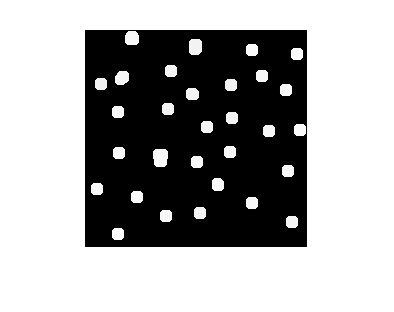

imgCircle = imopen(img6, SE6);
imshow(imgCircle)

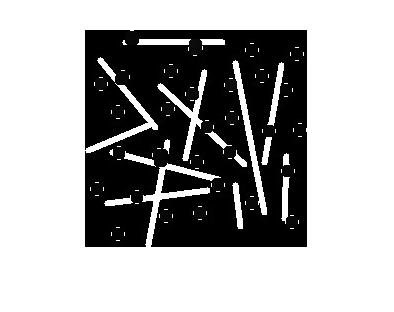

img7 = imsubtract(img6, imgCircle);
imshow(img7)

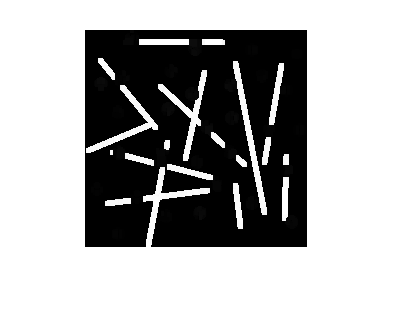

SE7 = strel('rectangle', [5 1]);
img8 = imopen(img7, SE7);
imshow(img8)